
clear all;
close all;

maindir='\\Artemis-pc\e\Data\2024-07-13\';
%load([maindir,'FreqRatio.mat']);
load([maindir,'FreqRatio_reduced.mat']);



% 数组必须左右对称 %

x = [-40 -20 ...
    20 40]*2.5;   % mGauss
y = [0.726060 0.726037 ...
    0.726079 0.726077];
err = [4 1 ...
    7 5]*1e-6;

% half_len = length(x)/2;
% x(half_len-1:half_len+2) = [];
% y(half_len-1:half_len+2) = [];
% err(half_len-1:half_len+2) = [];


% h1 = openfig([maindir,'R_vs_Current.fig']);
% ax1 = h1.Children.Children(2);
% x = ax1.XData/1e3; x(8) = [];
% y = ax1.YData; y(8) = [];
% err = ax1.YNegativeDelta; err(8) = [];


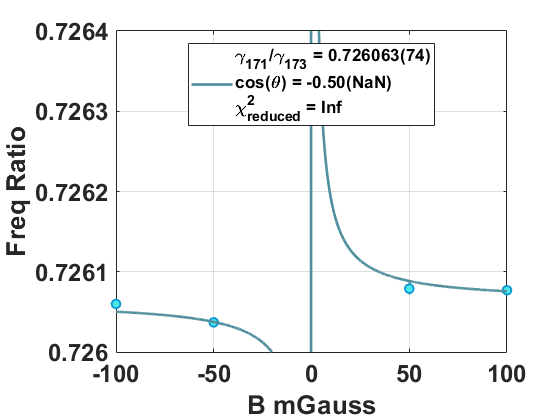


w = 1./err.^2;
%w_uni = w./sum(w);   % 归一化

x1 = x; y1 = y; err1 = err; w1 = w;

f1 = figure; hold on;
E1 = errorbar(x,y,err,'o', LineWidth=2, MarkerSize=6);

E1.CapSize = 0;
E1.MarkerEdgeColor = [0.04,0.59,0.83];
E1.MarkerFaceColor = [0.29,0.91,0.91];
E1.Color = [0.45,0.63,0.67];

set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'YScale','linear','XScale','linear');
ylim([0.726 0.7263]);
%xlim([-10 10]);
grid on;
box on;

%% 拟合: '无标题拟合 1'。
[xData, yData, weights] = prepareCurveData(x, y, w);

% 设置 fittype 和选项。
% ft1 = fittype( 'sqrt(R^2*(x)^2+I171^2-2*I171*R*(x)*a)/sqrt(1^2*(x)^2+I171/0.77^2-2*I171/0.77*1*(x)*a)',...
%     'independent', 'x', 'dependent', 'y' );
ft1 = fittype( 'sqrt(R^2*(x)^2+I171^2-2*I171*R*(x)*a)/sqrt(1^2*(x)^2+I173^2-2*I173*1*(x)*a)',...
    'independent', 'x', 'dependent', 'y' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [0 0 0.7260 -0.5];
opts1.Upper = [2 2 Inf 0.5];
opts1.StartPoint = [1 1 0.72608 0];
opts1.Weights = weights;

% 对数据进行模型拟合。
[fitresult1, gof1] = fit( xData, yData, ft1, opts1 );
R1 = fitresult1.R;
cos_theta = fitresult1.a;
I171 = fitresult1.I171;
I173 = fitresult1.I173;

interval = confint(fitresult1);
R1_sigma = (interval(2,3)-interval(1,3))/4;
cos_theta_sigma = (interval(2,4)-interval(1,4))/4;
I171_sigma = (interval(2,1)-interval(1,1))/4;
I173_sigma = (interval(2,2)-interval(1,2))/4;

l1 = plot( fitresult1, xData, yData );
l1(1).Marker = 'o';
l1(1).MarkerSize = 6;
l1(1).MarkerEdgeColor = [0.04,0.59,0.83];
l1(1).MarkerFaceColor = [0.29,0.91,0.91];
l1(2).Color = [0.32 0.56 0.62];
l1(2).LineWidth = 2;


% 计算 Chi square %
chi_square1 = 0;
for k1 = 1:length(x)
    temp1(k1) = (y(k1)-fitresult1(x(k1)))^2;
    chi_square1 = chi_square1 + w(k1)*temp1(k1);
end
chi_square1 = chi_square1/(length(x)-4);


legend('','',['\gamma_{171}/\gamma_{173} = ',num2str(roundn(R1,-6),'%.6f'),'(',num2str(round(R1_sigma*1e6)),')',...
      newline 'cos(\theta) = ',num2str(roundn(cos_theta,-2),'%.2f'),'(',num2str(round(cos_theta_sigma*100)),')',...
      newline '\chi^2_{reduced} = ',num2str(roundn(chi_square1,-2))], ...
      'Location','best','FontSize',13);

%legend('','',['\gamma_{171}/\gamma_{173} = ',num2str(roundn(R1,-6),'%.6f'),'(',num2str(round(R1_sigma*1e6)),')'], ...
%     'Location','best','FontSize',14);

xlabel('B mGauss');
ylabel('Freq Ratio');

hold off;

set(f1,'Visible','on');

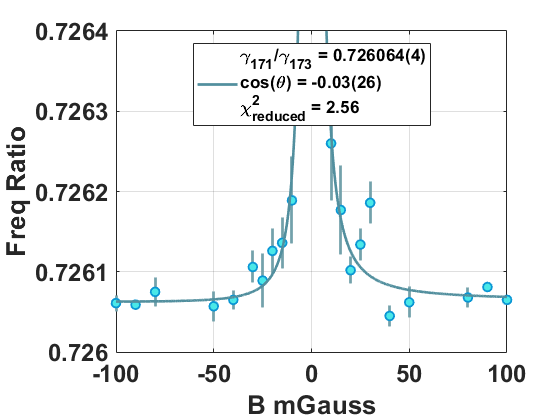


savefig(f1,[maindir,'Ratio_vs_B.fig']);
saveas(f1,[maindir,'Ratio_vs_B.png']);

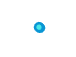


% 磁场电流数组必须左右对称 %


for k = 1:length(x)/2
    half = length(x)/2;
    x2(k) = 1/x(half+k)^2;
    y_mean(k) = (y(half+k)+y(half-k+1))/2;
    err_mean(k) = sqrt(err(half+k)^2+err(half-k+1)^2)/2;
end

w_mean = 1./err_mean.^2;

f2 = figure; hold on;
E2 = errorbar(x2,y_mean,err_mean,'o', LineWidth=2, MarkerSize=6);

E2.CapSize = 0;
E2.MarkerEdgeColor = [0.04,0.59,0.83];
E2.MarkerFaceColor = [0.29,0.91,0.91];
E2.Color = [0.45,0.63,0.67];

set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'YScale','linear','XScale','linear');
%ylim([0.3 1]);
%xlim([-40 40]);
grid on;
box on;



%% 拟合: '无标题拟合 2'。
[xData, yData, weights] = prepareCurveData(x2, y_mean, w_mean);

% 设置 fittype 和选项。
ft2 = fittype( 'slopes*x+R0',...
    'independent', 'x', 'dependent', 'y' );
opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts2.Display = 'Off';
opts2.Lower = [-Inf -Inf];
opts2.Upper = [Inf Inf];
opts2.StartPoint = [0.726 0];
opts2.Weights = weights;

% 对数据进行模型拟合。
[fitresult2, gof2] = fit( xData, yData, ft2, opts2 );
R2 = fitresult2.R0;
interval = confint(fitresult2);

错误使用 cfit/confint
如果观测值的数量 <= 系数的数量，则无法计算置信区间。

R2_sigma = (interval(2,1)-interval(1,1))/4;

l2 = plot( fitresult2, xData, yData );
l2(1).Marker = 'o';
l2(1).MarkerSize = 6;
l2(1).MarkerEdgeColor = [0.04,0.59,0.83];
l2(1).MarkerFaceColor = [0.29,0.91,0.91];
l2(2).Color = [0.32 0.56 0.62];
l2(2).LineWidth = 2;


% 计算 Chi square %
chi_square2 = 0;
for k1 = 1:length(x2)
    temp2(k1) = (y_mean(k1)-fitresult2(x2(k1)))^2;
    chi_square2 = chi_square2 + w_mean(k1)*temp2(k1);
end
chi_square2 = chi_square2/(length(x2)-2);


legend('','',['\gamma_{171}/\gamma_{173} = ',num2str(roundn(R2,-6),'%.6f'),'(',num2str(round(R2_sigma*1e6)),')',...
    newline '\chi^2_{reduced} = ',num2str(roundn(chi_square2,-2))], ...
    'Location','best','FontSize',14);

xlabel('B^{-2} mGauss^{-2}');
ylabel('Averaged Ratio');

hold off;

set(gcf,'Visible','on');


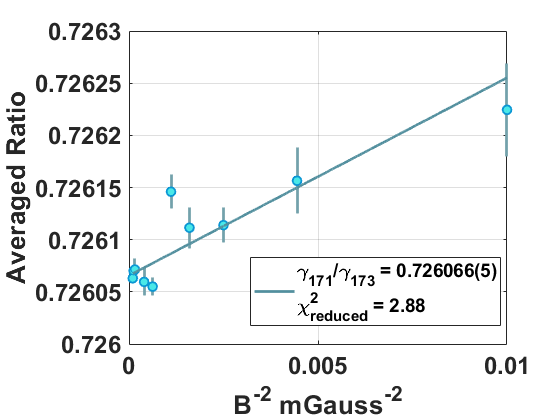


savefig(f2,[maindir,'Ratio_vs_B^-2.fig']);
saveas(f2,[maindir,'Ratio_vs_B^-2.png']);

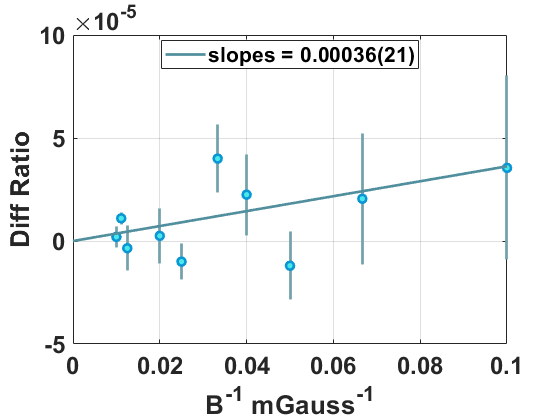


for k = 1:length(x)/2
    half = length(x)/2;
    x3(k) = 1/x(half+k);
    y_mean3(k) = (y(half+k)-y(half-k+1))/2;
end

f3 = figure; hold on;
E3 = errorbar(x3,y_mean3,err_mean,'o', LineWidth=2, MarkerSize=6);

E3.CapSize = 0;
E3.MarkerEdgeColor = [0.04,0.59,0.83];
E3.MarkerFaceColor = [0.29,0.91,0.91];
E3.Color = [0.45,0.63,0.67];

set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'YScale','linear','XScale','linear');
%ylim([0.3 1]);
%xlim([-40 40]);
grid on;
box on;


%% 拟合: '无标题拟合 3'。
[xData, yData, weights] = prepareCurveData(x3, y_mean3, w_mean);

% 设置 fittype 和选项。
ft3 = fittype( 'slopes*x',...
    'independent', 'x', 'dependent', 'y' );
opts3 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts3.Display = 'Off';
opts3.Lower = [-Inf];
opts3.Upper = [Inf];
opts3.StartPoint = [0];
opts3.Weights = weights;

% 对数据进行模型拟合。
[fitresult3, gof3] = fit( xData, yData, ft3, opts3 );

slope = fitresult3.slopes;
interval = confint(fitresult3);
slope_sigma = (interval(2,1)-interval(1,1))/4;

x_plot = [0 max(xData)];
y_plot = slope*x_plot;

plot(x_plot,y_plot,'Color',[0.32 0.56 0.62],'LineWidth',2);

xlabel('B^{-1} mGauss^{-1}');
ylabel('Diff Ratio');
legend('',['slopes = ',num2str(roundn(slope,-5),'%.5f'),'(',num2str(round(slope_sigma*1e5)),')'], ...
    'Location','best','FontSize',16);

hold off;

set(gcf,'Visible','on');


%savefig(f3,[maindir,'Diff_vs_B^-1.fig']);
%saveas(f3,[maindir,'Diff_vs_B^-1.png']);



save([maindir,'FreqRatio.mat']);

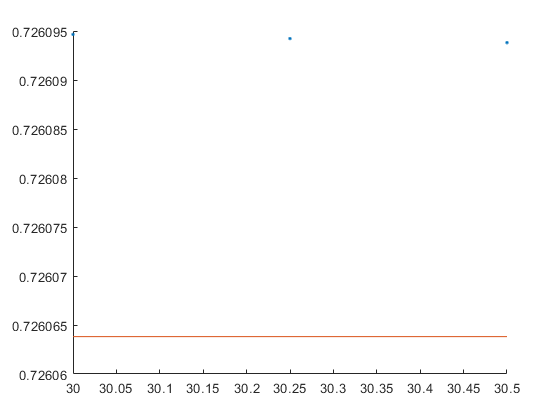


f3 = figure; hold on;

x_temp = [-100:0.1:100]*2.5;
B_temp = sqrt((x_temp + 0).^2+0^2);
cos_theta1=cos_theta-0/600;
y_temp = sqrt(R1^2*B_temp.^2+I171^2-2*I171*R1*B_temp*cos_theta1)./sqrt(B_temp.^2+I173^2-2*I173*B_temp*cos_theta1);

plot(x_temp,y_temp,'.');
%ylim([0.72605 0.7261]);
xlim([30 30.5])
plot([x_temp(1),x_temp(end)],[R1,R1]);

set(gcf,'Visible','on');